# **Ordinary Differential Equations**

## 1. $u^\prime=u^2$

### General Solutions and the Sigular Solution (Quadrature)


$$u(t)
=
\frac{C}{1-Ct}, 
\qquad
u(t)
=
-\frac{1}{t}
\quad
(|C|\rightarrow\infty).
$$


If we set $C_1=-1/C$, then


$$u(t)=-\frac{1}{C_1+t},
\qquad
u(t)\equiv0
\quad
(|C_1|\rightarrow\infty).$$


### General Solutions and the Sigular Solution (MATLAB)

syms u(t)
ode1=diff(u,t,1)-u^2;
u1(t)=dsolve(ode1)

$$u1(t) = \left(\begin{array}{c} -\frac{1}{C_{1}+t}\\ 0 \end{array}\right)$$

### Initial Value Problem

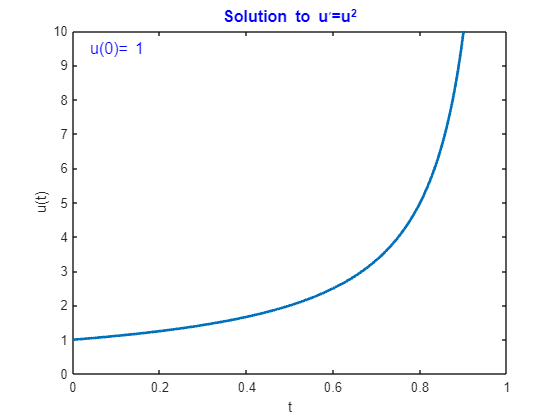

d1 =1;
data1=u(0)==d1;
U1(t)=dsolve(ode1,data1);
t=0:0.005:99/100/d1;
strd1=string(d1);
plot(t,U1(t),'LineWidth',2)
xlim([0,1/d1])
ylim([0,10*d1])
xlabel('t')
ylabel('u(t)')
text(1/25/d1,9.5*d1,'u(0)=','Color','blue','FontSize',12)
text(1/7/d1,9.5*d1,strd1,'Color','blue','FontSize',12)
title('Solution to u^\prime=u^2','Color','blue','FontSize',12)

## 2. $u^{\prime\prime}+2\gamma u^\prime + k^2 u = \sin(\omega t),
\quad
\gamma,k,\omega\geq0$

The roots of the characteristic polynomial $z^2+2\gamma z+k^2$ is $-\gamma\pm\sqrt{\gamma^2-k^2}$.

### General Solutions (Quadrature)

#### Case $\omega=0$, i.e., $u^{\prime\prime}+2\gamma u^\prime + k^2 u = 0$.

If $\gamma>k$, then 


$$u(t)
=
C_1e^{-\bigl(\gamma+\sqrt{\gamma^2-k^2}\bigr)t}
+
C_2e^{-\bigl(\gamma-\sqrt{\gamma^2-k^2}\bigr)t}.$$


If $\gamma=k$, then


$$u(t)=
C_1 e^{-\gamma t}
+
C_2te^{-\gamma t}.$$


If $\gamma<k$, then


$$u(t)
=
C_1e^{-\gamma t}\cos\bigl(t\sqrt{k^2-\gamma^2}\bigr)
+
C_2e^{-\gamma t}\sin\bigl(t\sqrt{\gamma^2-k^2}\bigr).$$


#### Case $\omega>0$.

If $\gamma>k$, then 


$$u(t)
=
C_1e^{-\bigl(\gamma+\sqrt{\gamma^2-k^2}\bigr)t}
+
C_2e^{-\bigl(\gamma-\sqrt{\gamma^2-k^2}\bigr)t}$$



$$\qquad
+
\int_0^t
\frac{e^{-\gamma(t-s)} \cosh\bigl\{(t-s)\sqrt{\gamma^2-k^2}\bigr\}}{\sqrt{\gamma^2-k^2}}
\sin(\omega s)
ds$$



$$\qquad
=
D_1e^{-\bigl(\gamma+\sqrt{\gamma^2-k^2}\bigr)t}
+
D_2e^{-\bigl(\gamma-\sqrt{\gamma^2-k^2}\bigr)t}$$



$$\qquad
+
\frac{\gamma(k^2+\omega^2)\sin(\omega t)-\omega(2\gamma^2-k^2+\omega^2)\cos(\omega t)}{\{(k^2-\omega^2)^2+4\gamma^2\omega^2\}\sqrt{\gamma^2-k^2}}.$$


If $\gamma=k$, then


$$u(t)=
C_1 e^{-\gamma t}
+
C_2te^{-\gamma t}
+
\int_0^t
(t-s)e^{-\gamma(t-s)}
\sin(\omega s)
ds$$



$$\qquad
=
D_1 e^{-\gamma t}
+
D_2te^{-\gamma t}
+
\frac{(\gamma^2-\omega^2)\sin(\omega t)-2\gamma\omega\cos(\omega t)}{(\gamma^2+\omega^2)^2}.$$


If $k>\gamma$, then


$$u(t)
=
C_1e^{-\gamma t}\cos\bigl(t\sqrt{k^2-\gamma^2}\bigr)
+
C_2e^{-\gamma t}\sin\bigl(t\sqrt{k^2-\gamma^2}\bigr)$$



$$\qquad
+
\int_0^t
\frac{e^{-\gamma(t-s)} \sin\bigl\{(t-s)\sqrt{k^2-\gamma^2}\bigr\}}{\sqrt{k^2-\gamma^2}}
\sin(\omega s)
ds.$$


If $k>\gamma$ and $\sqrt{k^2-\gamma^2}\ne\omega$, then


$$u(t)
=
D_1e^{-\gamma t}\cos\bigl(t\sqrt{k^2-\gamma^2}\bigr)
+
D_2e^{-\gamma t}\sin\bigl(t\sqrt{k^2-\gamma^2}\bigr)$$



$$\qquad
=
\frac{(k^2-\omega^2)\sin(\omega t) - 2\gamma\omega\cos(\omega t)}{(k^2-\omega^2)^2+4\gamma^2\omega^2}.$$


If $k>\gamma=0$ and $\sqrt{k^2-\gamma^2}=\omega$, i.e., $k=\omega$ and $\gamma=0$, then


$$u(t)
=
D_1\cos(\omega t)
+
D_2\sin(\omega t)
-
\frac{t}{2\omega}\cos(\omega t).$$


If $k>\gamma>0$ and $\sqrt{k^2-\gamma^2}=\omega$, then


$$u(t)
=
D_1e^{-\gamma t}\cos\bigl(t\sqrt{k^2-\gamma^2}\bigr)
+
D_2e^{-\gamma t}\sin\bigl(t\sqrt{k^2-\gamma^2}\bigr)$$



$$\qquad
+
\frac{\omega\sin(\omega t)+\gamma\cos(\omega t)}{4\omega^3}
-
\frac{1-e^{-\gamma t}}{2\gamma\omega}
\cos(\omega t),$$



$$\frac{1-e^{-\gamma t}}{2\gamma\omega}
\cos(\omega t)
=
\frac{t}{2\omega}
\bigl(1+\mathcal{O}(\gamma)\bigr)
\cos(\omega t),
\quad
(\gamma \downarrow0).$$


### General Solutions (MATLAB)

The classification does not seem to work.

syms u(t) gamma k omega
ode2=diff(u,t,2)+2*gamma*diff(u,t,1)+k^2*u-sin(omega*t);
u2(t)=dsolve(ode2)

$$u2(t) = \begin{array}{l} C_{1}\,\sigma_{4}+C_{2}\,\sigma_{3}+\frac{\sigma_{4}\,{\mathrm{e}}^{\gamma \,t+t\,\sigma_{1}}\,\left(\sigma_{2}-\sin\left(\omega \,t\right)\,\left(\gamma +\sigma_{1}\right)\right)}{2\,\left(\omega^{2}+{\left(\gamma +\sigma_{1}\right)}^{2}\right)\,\sigma_{1}}-\frac{{\mathrm{e}}^{\gamma \,t-t\,\sigma_{1}}\,\sigma_{3}\,\left(\sigma_{2}-\sin\left(\omega \,t\right)\,\left(\gamma -\sigma_{1}\right)\right)}{2\,\sigma_{1}\,\left({\left(\gamma -\sigma_{1}\right)}^{2}+\omega^{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\gamma^{2}-k^{2}}\\ \sigma_{2}=\omega \,\cos\left(\omega \,t\right)\\ \sigma_{3}={\mathrm{e}}^{-t\,\left(\gamma -\sigma_{5}\right)}\\ \sigma_{4}={\mathrm{e}}^{-t\,\left(\gamma +\sigma_{5}\right)}\\ \sigma_{5}=\sqrt{\left(\gamma +k\right)\,\left(\gamma -k\right)} \end{array}$$

### Initial Value Problem

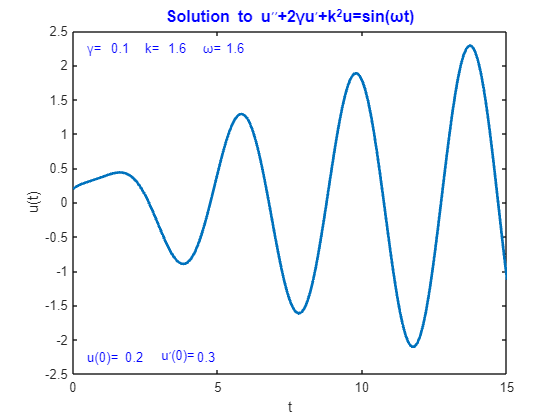

gamma =0.1; k = 1.6; 
omega = 1.6;
d20 = 0.2; d21 = 0.3;
syms u(t)
Du=diff(u,t);
ode3=diff(u,t,2)+2*gamma*diff(u,t,1)+k^2*u-sin(omega*t);
data20=u(0)==d20;
data21=Du(0)==d21;
data2=[data20 data21];
U2(t)=dsolve(ode3,data2);
t=0:0.1:15;
strg=string(gamma);
strk=string(k);
stromg=string(omega);
strd20=string(d20);
strd21=string(d21);
plot(t,U2(t),'LineWidth',2)
ylim([-5*d20-5*d21,5*d20+5*d21])
xlabel('t')
ylabel('u(t)')
text(0.5,4.5*d20+4.5*d21,'γ=','Color','blue','FontSize',10)
text(1.3,4.5*d20+4.5*d21,strg,'Color','blue','FontSize',10)
text(2.5,4.5*d20+4.5*d21,'k=','Color','blue','FontSize',10)
text(3.3,4.5*d20+4.5*d21,strk,'Color','blue','FontSize',10)
text(4.5,4.5*d20+4.5*d21,'ω=','Color','blue','FontSize',10)
text(5.3,4.5*d20+4.5*d21,stromg,'Color','blue','FontSize',10)
text(0.5,-4.5*d20-4.5*d21,'u(0)=','Color','blue','FontSize',10)
text(1.8,-4.5*d20-4.5*d21,strd20,'Color','blue','FontSize',10)
text(3,-4.5*d20-4.5*d21,'u^\prime(0)=','Color','blue','FontSize',10)
text(4.3,-4.5*d20-4.5*d21,strd21,'Color','blue','FontSize',10)
title('Solution to u^{\prime\prime}+2γu^\prime+k^2u=sin(ωt)','Color','blue','FontSize',12)

## 3.  $\frac{d}{dt}
\pmatrix{x(t) \cr y(t)} 
=
\pmatrix{a & b \cr c & d}
\pmatrix{x(t) \cr y(t)},
\quad
a,b,c,d\in\mathbb{R}$

Set 


$$A
=
\pmatrix{a & b \cr c & d}.$$


Solutions to this system of differential equations are integral curves of the planar vector field 


$$\vec{V}(x,y)
=
\pmatrix{a & b \cr c & d}
\pmatrix{x \cr y}
=
\pmatrix{ax+by \cr cx+dy}$$


on the $xy$-plane. The eigen values of the matrix $A$ are 


$$\lambda=\frac{a+d+\sqrt{(a-d)^2+4bc}}{2}, 
\quad
\mu=\frac{a+d-\sqrt{(a-d)^2+4bc}}{2}.$$


### General Solution (Quadrature)


$$\vec{x}(t)
=
e^{tA}
\vec{C}, 
\quad
\vec{x}(t)
:=
\pmatrix{x(t) \cr y(t)},
\quad
\vec{C}
:=
\pmatrix{C_1 \cr C_2}.$$


The matrix exponential $e^{tA}$ is explicitly given as follows. 

If $\lambda\ne\mu$, i.e., $(a-d)^2+4bc\ne0$, then 


$$e^{tA}
=
\frac{e^{\lambda t}}{\lambda-\mu}(A-\mu E)
+
\frac{e^{\mu t}}{\mu-\lambda}(A-\lambda E).$$


If $\lambda=\mu$, i.e., $(a-d)^2+4bc=0$, then 


$$e^{tA}
=
e^{\lambda t}E
+
te^{\lambda t}(A-\lambda E).$$


### General Solution (MATLAB)

The classification does not seem to work.

syms x(t) y(t) a b c d
ode4=[diff(x,t)==a*x+b*y, diff(y,t)==c*x+d*y];
u3=dsolve(ode4)

u3 = struct with fields:
    y: C1*exp((t*(a + d + (a^2 - 2*a*d + d^2 + 4*b*c)^(1/2)))/2) + C2*exp((t*(a + d - (a^2 - 2*a*d + d^2 + 4*b*c)^(1/2)))/2)
    x: - C1*exp((t*(a + d + (a^2 - 2*a*d + d^2 + 4*b*c)^(1/2)))/2)*(d/c - (a/2 + d/2 + (a^2 - 2*a*d + d^2 + 4*b*c)^(1/2)/2)/c) - C2*exp((t*(a + d - (a^2 - 2*a*d + d^2 + 4*b*c)^(1/2)))/2)*(d/c - (a/2 + d/2 - (a^2 - 2*a*d + d^2 + 4*b*c)^(1/2)/2)/c)


### Vector Field and Integral Curves

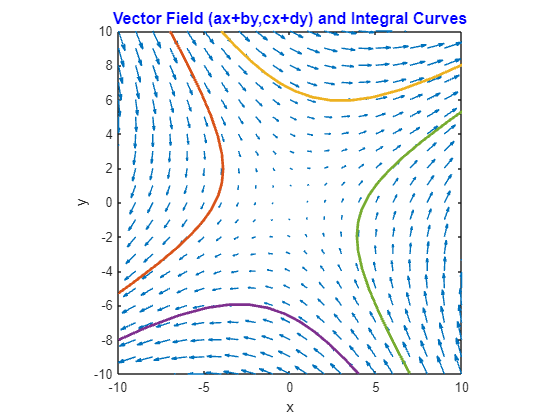

a =1; b = 2;
c =2; d = -1;
A=[a b;c d];
[t1,z1]=ode45(@(t,z) A*z,[-2,2], [-7;10]);
[t2,z2]=ode45(@(t,z) A*z,[-2,2], [-4;10]);
[t3,z3]=ode45(@(t,z) A*z,[-2,2], [4;-10]);
[t4,z4]=ode45(@(t,z) A*z,[-2,2], [7;-10]);

[x,y]=meshgrid(-10:1:10, -10:1:10);
X=a*x+b*y; Y=c*x+d*y;
quiver(x,y,X,Y);
xlim([-10,10]);
ylim([-10,10]);
xlabel x;
ylabel y;
axis equal;
axis([-10 10 -10 10])
title('Vector Field (ax+by,cx+dy) and Integral Curves','Color','blue','FontSize',12);
hold on 
plot(z1(:,1),z1(:,2),z2(:,1),z2(:,2),z3(:,1),z3(:,2),z4(:,1),z4(:,2),'LineWidth',2)
hold off